x = [-3,-2,-1,0,1,2,3]

x =     -3    -2    -1     0     1     2     3


y = [1,0,0,-1,-1,0,0]

y =      1     0     0    -1    -1     0     0


x_vec = [ones(7,1),x',(x.^2)']

x_vec =      1    -3     9
     1    -2     4
     1    -1     1
     1     0     0
     1     1     1
     1     2     4
     1     3     9


y_vec = y'

y_vec =      1
     0
     0
    -1
    -1
     0
     0


x_vec'*x_vec

ans =      7     0    28
     0    28     0
    28     0   196


x_vec'*y_vec

ans =     -1
    -4
     8


beta = inv(x_vec'*x_vec)*(x_vec'*y_vec)

beta =    -0.7143
   -0.1429
    0.1429


x_plot = [-3:0.1:3]

x_plot =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


y_plot = beta(1,1)+beta(2,1).*x_plot+beta(3,1).*(x_plot.^2)

y_plot =     1.0000    0.9014    0.8057    0.7129    0.6229    0.5357    0.4514    0.3700    0.2914    0.2157    0.1429    0.0729    0.0057   -0.0586   -0.1200   -0.1786   -0.2343   -0.2871   -0.3371   -0.3843   -0.4286   -0.4700   -0.5086   -0.5443   -0.5771   -0.6071   -0.6343   -0.6586   -0.6800   -0.6986   -0.7143   -0.7271   -0.7371   -0.7443   -0.7486   -0.7500   -0.7486   -0.7443   -0.7371   -0.7271   -0.7143   -0.6986   -0.6800   -0.6586   -0.6343   -0.6071   -0.5771   -0.5443   -0.5086   -0.4700


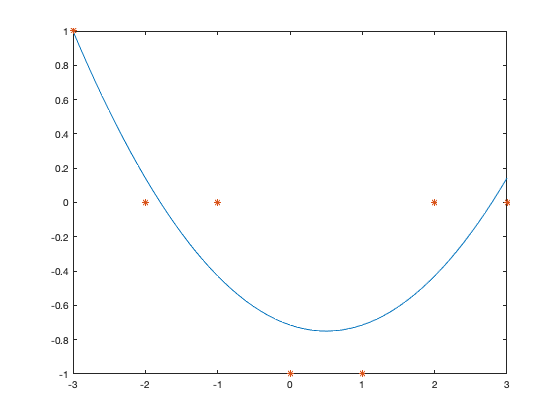

plot(x_plot,y_plot)
hold on
plot(x,y,'*')
hold off